%Get number of cases run
numeach = zeros(200, 1);
for j = 1:200
    partitionno = j;
    if exist(sprintf('ImpData_old/progress%d.mat', partitionno), "file")
        numsims = load(sprintf('ImpData_old/progress%d.mat', partitionno)).i;
    else
        continue
    end
    numeach(partitionno) = numsims;


end
sum(numeach) 

ans = 1103000

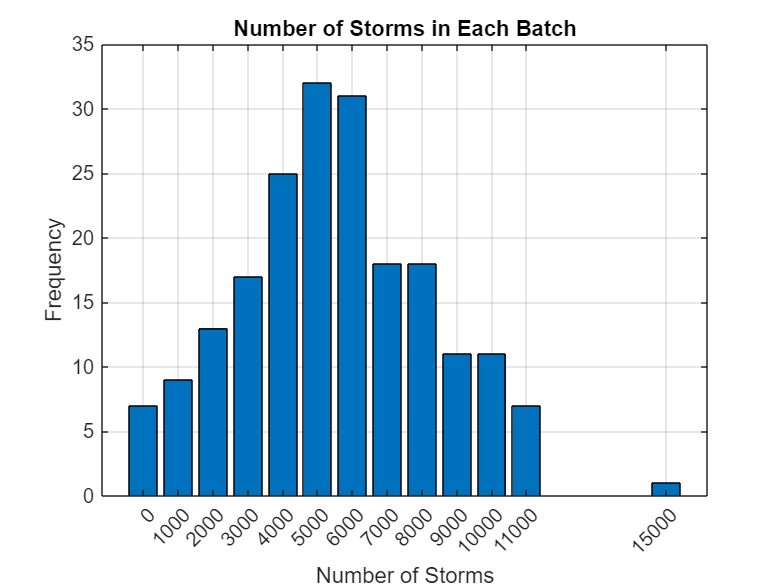

[unique_vals, ~, idx] = unique(numeach);
counts = accumarray(idx, 1);
bar(unique_vals, counts);
xlabel('Number of Storms');
ylabel('Frequency');
title('Number of Storms in Each Batch');
grid on;

zero_indices = find(numeach == 0);
disp(zero_indices);

numlines = zeros(sum(numeach) , 1);
numbuses = zeros(sum(numeach) , 1);
%make it total, lines, buses removed
i = 1;
for j = 1:200
    partitionno = j;
    if exist(sprintf('ImpData/progress%d.mat', partitionno), "file")
        data = load(sprintf('ImpData/outputstruct%d.mat', partitionno)).fulloutputstruct;
    else
        continue
    end
    for k = 1:numeach(j) %numeach(j) holds the number of sims per partition
        numlines(i) = size(data(k).caseremlineimportances, 1);
        numbuses(i) = size(data(k).caserembusimportances, 1);
        i = i+1;
        if mod(i, 2000) == 0
            i
        end
    end    
end

load('Temp Files\numlinesineachcase.mat', numlines)
load('Temp Files\numbusesineachcase.mat', numbuses)

%%use stuff above
[unique_valslines, ~, idxlines] = unique(numlines);
countslines = accumarray(idxlines, 1);


[unique_valsbuses, ~, idxbuses] = unique(numbuses);
countsbuses = accumarray(idxbuses, 1);

numassets = numlines + numbuses;
nnz(numassets)
[unique_valsassets, ~, idxassets] = unique(numassets);
countslines = accumarray(idxassets, 1);
bar(unique_valsassets, countslines);
xlabel('Number of Tornadoes');
ylabel('Frequency');
title('Number of Assets removed in each case');
set(gca, 'YScale', 'log')
grid on;

subplot(1,2,1); % 1 row, 2 columns, first subplot
bar(unique_valslines, countslines);
title('Number of Lines removed in each case');
xlabel('Number of Tornadoes');
ylabel('Frequency');
set(gca, 'YScale', 'log')
grid on;

% Second subplot
subplot(1,2,2); % 1 row, 2 columns, second subplot
bar(unique_valsbuses, countsbuses);
title('Number of Buses removed in each case');
xlabel('Number of Tornadoes');
ylabel('Frequency');
set(gca, 'YScale', 'log')
grid on;

totalbusimportanceData = table([], [], [], 'VariableNames', {'bus', 'importance', 'hits'});

for i = 1:200
    partitionno = i;
    if exist(sprintf('ImpData_old/busimp%d.mat', partitionno), "file")
        simbusimportances = load(sprintf('ImpData_old/busimp%d.mat', partitionno)).totalbusimportanceData;
    else
        continue
    end
    for j = 1:size(simbusimportances, 1)
        if ~isempty(totalbusimportanceData.bus)
            [isInTable, rowIdx] = ismember(simbusimportances.bus(j), totalbusimportanceData.bus); % Check if index is in the table
        else
            isInTable = false;
        end
    
        if isInTable
            % Update the value
            totalbusimportanceData.importance(rowIdx) = totalbusimportanceData.importance(rowIdx) + simbusimportances.importance(j);
            totalbusimportanceData.hits(rowIdx) = totalbusimportanceData.hits(rowIdx) + 1;
        else
            % Append a new row
            newRow = {simbusimportances.bus(j), simbusimportances.importance(j), 1};
            totalbusimportanceData = [totalbusimportanceData; newRow];
        end
    end
    if mod(i, 40) == 0
        disp(i)
    end
end

    40

    80

   120

   160

   200



totallineimportanceMap = containers.Map('KeyType', 'char', 'ValueType', 'any');

for i = 1:200
    partitionno = i;
    fileName = sprintf('ImpData_old/lineimp%d.mat', partitionno);
    if exist(fileName, "file")
        simlineimportances = load(fileName).totallineimportanceData;
    else
        continue
    end

    for j = 1:size(simlineimportances, 1)
        % Create a unique key for fast lookup
        key = sprintf('%d-%d-%d', simlineimportances.line(j).busfrom, ...
                                   simlineimportances.line(j).busto, ...
                                   simlineimportances.line(j).connumber);
        if isKey(totallineimportanceMap, key)
            % Update existing entry
            entry = totallineimportanceMap(key);
            entry.importance = entry.importance + simlineimportances.importance(j);
            entry.hits = entry.hits + 1;
            totallineimportanceMap(key) = entry;
        else
            % Add new entry
            totallineimportanceMap(key) = struct( ...
                'line', simlineimportances.line(j), ...
                'importance', simlineimportances.importance(j), ...
                'hits', 1);
        end
    end

    if mod(i, 40) == 0
        disp(i)
    end
end

    40

    80

   120

   160

   200




% Convert the map to a table
keys = totallineimportanceMap.keys;
numEntries = length(keys);
lineArr = cell(numEntries, 1);
importanceArr = zeros(numEntries, 1);
hitsArr = zeros(numEntries, 1);

for i = 1:numEntries
    entry = totallineimportanceMap(keys{i});
    lineArr{i} = entry.line;
    importanceArr(i) = entry.importance;
    hitsArr(i) = entry.hits;
end

totallineimportanceData = table(lineArr, importanceArr, hitsArr, ...
    'VariableNames', {'line', 'importance', 'hits'});
